%reading the audio file
[a fs]=audioread("C:\Users\pooja\Desktop\Cryptography\sig100.wav")

a =    -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0283   -0.0127
   -0.0234   -0.0156
   -0.0264   -0.0156


fs = 360

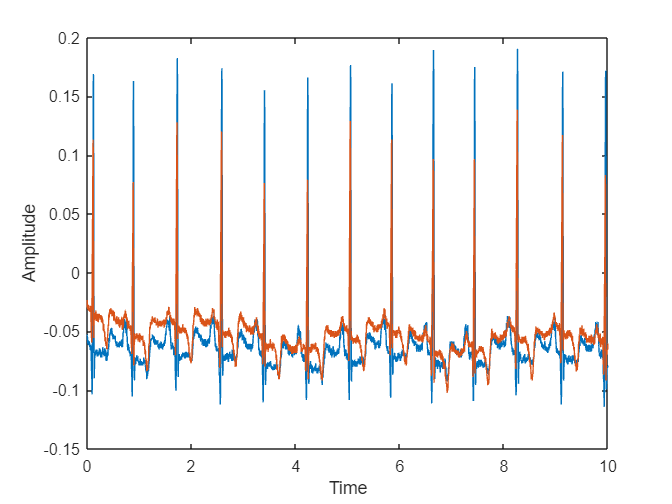


%extracting the first 10 seconds of the audio file
a_cut = a((fs * (10-1)) + 1 : fs * (20-1), :);

t_og = (0:length(a_cut)-1) / fs;
plot(t_og, a_cut)
xlabel('Time')
ylabel('Amplitude')


% Determine minimum and maximum values in each channel
ecg_min = min(a_cut);
ecg_max = max(a_cut);

% Shift the range so that it starts at 0
ecg_shifted = a_cut - ecg_min;

% Divide each value by the range of values to scale the waveform
ecg_normalized = zeros(size(ecg_shifted));
ecg_normalized(:,1) = ecg_shifted(:,1) / (ecg_max(1) - ecg_min(1));
ecg_normalized(:,2) = ecg_shifted(:,2) / (ecg_max(2) - ecg_min(2));

% Check the size and values of the normalized ECG waveform
disp(size(ecg_normalized));

        3600           2



disp(ecg_normalized(1:10,:));

    0.2019    0.3279
    0.1987    0.3036
    0.1923    0.3036
    0.1827    0.2996
    0.1827    0.2955
    0.1731    0.3077
    0.1795    0.3117
    0.1827    0.3077
    0.1859    0.3077
    0.1827    0.2955




% Generate Bernstein polynomial approximations of order 1000 for both channels
n = 1000;
t = linspace(0, 1, size(ecg_normalized, 1));
p = bernstein(n, t);

x1 = ecg_normalized(:, 1); % Select the first channel of the normalized ECG waveform
a1 = p \ x1;

y1 = p * a1;

x2 = ecg_normalized(:, 2); % Select the second channel of the normalized ECG waveform
a2 = p \ x2;

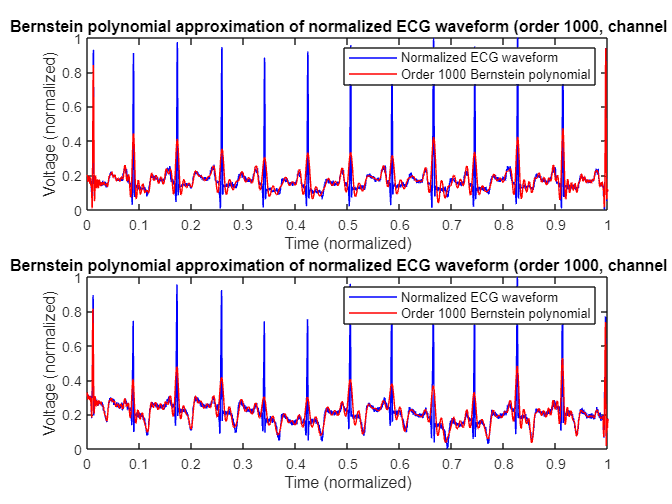

y2 = p * a2;

% Plot the normalized ECG waveform and the Bernstein polynomial approximations for both channels
figure;
subplot(2, 1, 1);
plot(t, ecg_normalized(:, 1), 'b');
hold on;
plot(t, y1, 'r');
xlabel('Time (normalized)');
ylabel('Voltage (normalized)');
title('Bernstein polynomial approximation of normalized ECG waveform (order 1000, channel 1)');
legend('Normalized ECG waveform', 'Order 1000 Bernstein polynomial');

subplot(2, 1, 2);
plot(t, ecg_normalized(:, 2), 'b');
hold on;
plot(t, y2, 'r');
xlabel('Time (normalized)');
ylabel('Voltage (normalized)');
title('Bernstein polynomial approximation of normalized ECG waveform (order 1000, channel 2)');
legend('Normalized ECG waveform', 'Order 1000 Bernstein polynomial');
hold off


% Plot

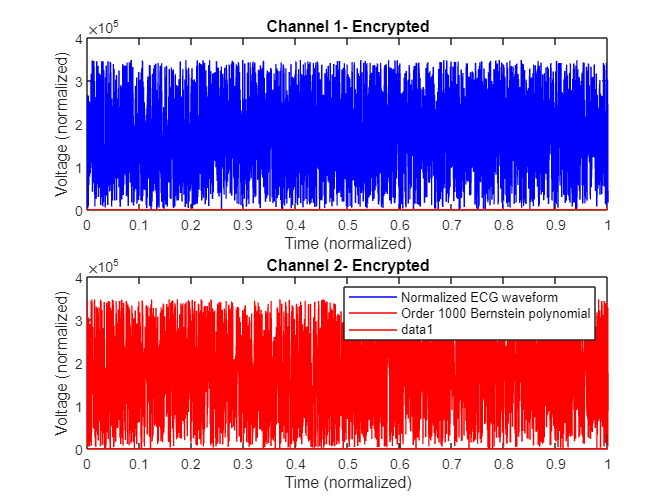

% Generate RSA keys
p = 587;
q = 593;
n = p * q;
phi = (p - 1) * (q - 1);
e = 65537;
d = modinv(e, phi);

% Convert the Bernstein polynomial approximations to integers for encryption
M1 = floor(y1 * 2^16);
M2 = floor(y2 * 2^16);

% Encrypt the integer representations using RSA
C1 = powermod(M1, e, n);
C2 = powermod(M2, e, n);

% Decrypt the encrypted integers using RSA
D1 = powermod(C1, d, n);
D2 = powermod(C2, d, n);

% Convert the decrypted integers back to Bernstein polynomial approximations
y1_decrypted = mod(D1, 2^16) / 2^16;
y2_decrypted = mod(D2, 2^16) / 2^16;


% Plot the normalized ECG waveform and the Bernstein polynomial approximations for both channels
figure;
subplot(2, 1, 1);
plot(t, ecg_normalized(:, 1), 'b');
hold on;
plot(t, y1, 'r');
xlabel('Time (normalized)');
ylabel('Voltage (normalized)');
title('Bernstein polynomial approximation of normalized ECG waveform (order 1000, channel 1)');
legend('Normalized ECG waveform', 'Order 1000 Bernstein polynomial');

subplot(2, 1, 2);
plot(t, ecg_normalized(:, 2), 'b');
hold on;
plot(t, y2, 'r');
xlabel('Time (normalized)');
ylabel('Voltage (normalized)');
title('Bernstein polynomial approximation of normalized ECG waveform (order 1000, channel 2)');
legend('Normalized ECG waveform', 'Order 1000 Bernstein polynomial');




% Plot the encrypted ECG waveform for both channels
subplot (2,1,1)
plot(t, C1, 'b');
xlabel('Time (normalized)');
ylabel('Voltage (normalized)');
title('Channel 1- Encrypted');
legend ('off')
subplot (2,1,2)
plot(t, C2, 'r');
xlabel('Time (normalized)');
ylabel('Voltage (normalized)');
title('Channel 2- Encrypted');

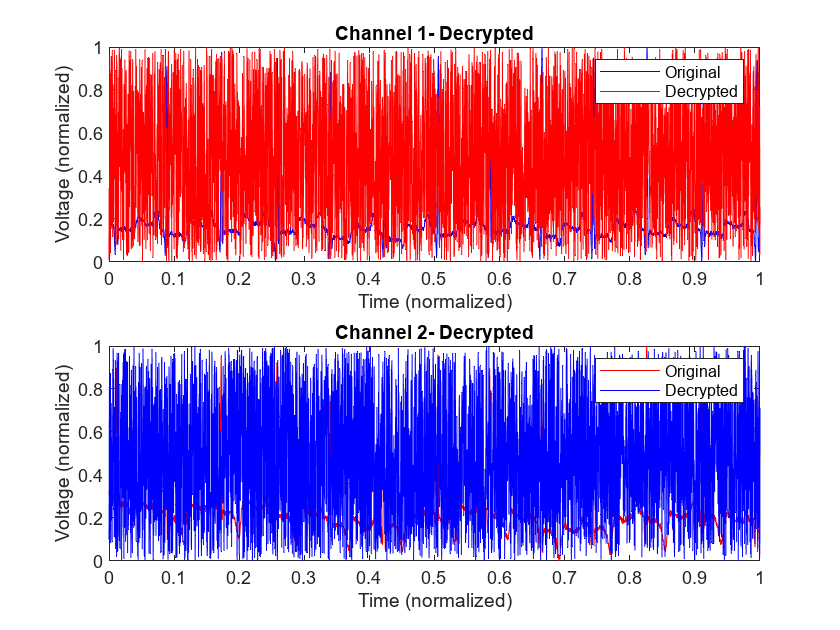


% Plot the original and decrypted ECG waveform for both channels
figure
subplot(2, 1, 1)
plot(t, ecg_normalized(:,1), 'b');
hold on;
plot(t, y1_decrypted, 'r');
hold off;
xlabel('Time (normalized)');
ylabel('Voltage (normalized)');
title('Channel 1- Decrypted');
legend('Original', 'Decrypted');
subplot(2, 1, 2)
plot(t, ecg_normalized(:,2), 'r');
hold on;
plot(t, y2_decrypted, 'b');
hold off;
xlabel('Time (normalized)');
ylabel('Voltage (normalized)');
title('Channel 2- Decrypted');
legend('Original', 'Decrypted');